# House Price-to-Income Ratio Analysis

Source: Eurostat - Standardised house price-to-income ratio (annual data) Dataset: tipsho60__custom_20309360 | Last updated: 09/01/2026 Coverage: EU member states, 2000-2024

## 1. Load Data

----------------------------------------------------------------- Years (2000-2024, 25 observations)

years = 2000:2024;

% --- Sheet 1: Annual rate of change (%) ---
countries = { ...
    'Belgium','Bulgaria','Czechia','Denmark','Germany', ...
    'Estonia','Ireland','Greece','Spain','France', ...
    'Croatia','Italy','Cyprus','Latvia','Lithuania', ...
    'Luxembourg','Hungary','Malta','Netherlands','Austria', ...
    'Poland','Portugal','Romania','Slovenia','Slovakia', ...
    'Finland','Sweden'};

% Data matrix: rows = countries, cols = years 2000-2024
% NaN = data not available
rateOfChange = [ ...
    NaN,0.4,4.5,4.9,6.1,9.5,5.0,3.2,-0.8,-1.4,1.4,1.1,0.1,0.6,-1.4,1.1,-0.1,0.3,0.0,0.1,2.9,1.0,-2.9,-4.8,0.5; ...
    NaN,-10.1,-20.8,4.7,35.1,22.9,0.8,15.0,1.8,-22.9,-11.8,-13.9,-3.7,-5.6,-0.8,-1.8,1.5,0.1,-5.2,-0.6,2.5,-2.9,-4.6,-4.8,-9.2; ...
    NaN,1.8,6.2,5.1,-4.8,-2.1,0.5,13.0,4.6,-4.2,-4.3,-1.1,-2.5,-0.2,-1.4,0.9,3.1,3.7,0.9,2.1,2.0,9.1,7.1,-9.1,0.1; ...
    NaN,0.3,-1.0,-0.1,5.2,13.9,18.8,1.3,-7.8,-15.3,-1.3,-3.9,-4.0,3.4,2.9,3.6,1.2,2.7,1.6,0.3,3.4,7.6,-1.9,-7.4,0.3; ...
    NaN,-3.9,-2.5,-2.3,-3.1,-1.0,-2.9,-4.6,-1.4,0.0,-1.5,0.3,1.3,1.2,0.3,2.1,4.6,2.7,2.7,2.6,6.0,6.9,-1.9,-12.5,-5.4; ...
    NaN,NaN,NaN,NaN,NaN,NaN,24.9,3.1,-21.9,-31.9,6.5,0.3,2.9,1.1,9.0,-0.3,-0.1,-1.8,-5.7,0.6,3.8,5.7,8.7,-1.0,-1.0; ...
    NaN,1.3,-2.4,7.4,5.0,2.0,9.4,2.0,-10.4,-13.0,-9.5,-16.3,-14.5,2.1,15.5,7.0,3.7,5.5,6.7,-3.2,-3.9,3.4,6.1,-6.0,1.6; ...
    NaN,8.0,4.8,-4.0,-4.2,7.9,4.3,-0.6,-5.5,-5.0,5.5,3.9,-0.1,-4.4,-6.6,-6.4,-2.0,-1.9,1.6,-0.1,7.9,-2.4,5.3,4.9,4.7; ...
    NaN,2.6,10.3,11.2,11.7,5.8,10.4,5.8,-5.5,-6.4,-1.7,-7.6,-9.9,-8.9,-0.2,-0.7,2.1,3.2,4.0,0.9,3.7,-1.4,3.0,-3.9,2.3; ...
    NaN,3.4,4.4,9.1,11.3,11.9,7.0,2.0,-1.8,-6.5,2.2,4.0,-1.4,-1.5,-2.6,-2.1,-0.3,0.9,0.9,0.7,4.0,1.2,1.6,-6.9,-7.7; ...
    NaN,-9.0,4.1,-3.9,2.7,4.6,11.7,2.6,-1.9,-4.0,-8.2,-1.2,-0.7,-4.2,-2.8,-2.2,-4.5,0.0,-0.6,2.8,5.0,-5.0,2.9,-0.6,-1.4; ...
    NaN,0.8,7.5,2.9,2.9,4.4,2.4,2.2,1.5,1.7,1.7,-0.2,0.5,-6.5,-5.4,-5.0,-1.2,-3.3,-2.2,-1.0,3.0,-2.9,-2.5,-3.7,0.1; ...
    NaN,-3.9,4.0,3.2,0.3,0.5,5.4,6.5,-4.1,-5.7,-5.7,-1.6,0.7,-0.2,6.3,-1.4,-4.2,-0.4,-6.4,-1.0,3.4,-6.3,1.3,3.2,0.4; ...
    NaN,-7.3,29.1,7.5,-14.1,36.7,-8.0,10.5,-15.9,-26.0,-7.0,7.8,-4.4,2.2,0.4,-9.3,2.2,1.0,0.9,2.1,0.9,0.7,3.7,-2.1,-3.8; ...
    NaN,7.3,-1.4,1.0,-3.2,-4.7,25.7,12.6,-11.3,-24.9,-8.1,0.0,-3.6,-4.8,3.0,-1.4,-2.9,5.9,-1.3,-3.1,-2.2,4.4,5.8,1.2,2.3; ...
    NaN,8.0,1.0,8.6,11.0,20.3,2.1,-1.6,-0.6,-3.5,2.9,0.9,1.1,1.1,3.2,5.5,6.1,1.0,3.9,6.0,7.4,12.3,4.5,-14.0,-9.3; ...
    NaN,3.6,2.0,6.4,-3.3,-5.0,-1.0,5.2,-1.6,-5.2,-5.2,-9.2,-5.8,-5.8,-0.9,7.6,7.1,2.2,2.9,5.6,0.7,1.7,2.9,-8.9,2.0; ...
    NaN,8.3,8.9,11.4,14.4,3.8,12.8,13.2,8.8,-5.8,-4.0,-5.9,-0.6,-5.4,-0.2,-0.8,0.2,-0.6,-0.4,0.2,-0.8,-4.2,0.9,-2.2,-4.4; ...
    NaN,0.7,2.0,0.6,2.3,3.3,-2.2,0.6,-1.2,-5.7,-3.2,-3.2,-6.8,-6.0,-1.1,1.8,2.9,5.7,4.4,2.3,4.5,7.7,6.0,-8.7,2.3; ...
    NaN,-0.2,-0.9,-3.0,-4.3,8.7,-0.6,-0.6,-1.9,-0.1,0.7,4.0,2.5,5.6,1.9,4.1,3.9,2.9,2.7,3.9,6.9,5.6,3.2,-8.4,-7.0; ...
    NaN,NaN,NaN,NaN,NaN,NaN,28.7,38.8,-8.5,-10.0,-9.7,-4.5,-7.5,-5.9,-4.4,-1.5,-2.6,-1.3,0.5,1.3,0.4,4.0,-0.2,-4.4,3.0; ...
    NaN,0.5,-3.7,-1.4,-2.8,1.5,-0.6,-2.7,-2.8,-2.0,-0.2,-1.9,-3.9,-1.8,4.0,-0.8,3.5,6.1,5.3,5.2,9.3,3.2,4.3,0.7,0.0; ...
    NaN,NaN,NaN,33.7,7.6,20.7,8.2,51.5,-10.6,-26.4,-14.6,-17.2,-9.0,-1.3,-4.9,-4.3,-4.2,-8.0,-2.7,-12.9,0.5,-4.2,-6.2,-9.7,-8.3; ...
    NaN,-4.8,-6.4,1.7,2.9,8.3,11.2,13.8,-1.2,-8.8,-1.3,0.8,-4.6,-4.5,-7.2,-1.1,-1.0,3.4,2.7,1.0,-0.2,3.3,5.6,-0.6,1.6; ...
    NaN,NaN,NaN,31.5,2.8,-15.1,5.8,14.6,5.6,-14.1,-6.7,-2.5,-5.3,-0.2,-0.9,0.2,3.9,1.3,-1.3,3.6,5.2,-0.5,3.4,-8.3,-3.5; ...
    NaN,-5.5,1.6,1.5,3.0,5.2,3.1,0.5,-4.7,-1.0,2.5,-0.8,-0.4,-0.5,-1.1,-1.8,0.1,-0.6,-2.3,-3.0,0.5,0.9,-3.0,-12.5,-4.8; ...
    NaN,0.8,0.3,3.3,7.5,6.1,6.8,6.1,-3.7,0.4,4.7,-1.1,-2.1,3.3,6.7,9.8,4.1,4.1,-3.8,-0.4,3.7,4.1,-2.2,-10.2,-3.1];

% --- Sheet 2: Price-to-income index (2015 = 100) ---
ptiIndex = [ ...
    71.54,71.85,75.11,78.82,83.63,91.59,96.17,99.29,98.47,97.06,98.45,99.58,99.67,100.27,98.9,100.0,99.89,100.21,100.24,100.39,103.29,104.36,101.34,96.43,96.9; ...
    131.99,118.71,93.96,98.39,132.95,163.46,164.72,189.34,192.83,148.71,131.23,113.04,108.83,102.71,101.87,100.0,101.5,101.65,96.34,95.78,98.18,95.34,91.0,86.6,78.64; ...
    90.68,92.34,98.03,102.98,98.01,96.0,96.49,109.0,114.0,109.18,104.45,103.3,100.66,100.44,99.08,100.0,103.13,106.93,107.94,110.19,112.36,122.58,131.3,119.31,119.4; ...
    89.34,89.57,88.66,88.58,93.14,106.09,125.99,127.58,117.6,99.63,98.32,94.49,90.71,93.81,96.52,100.0,101.24,103.98,105.63,105.92,109.51,117.79,115.56,106.98,107.28; ...
    120.25,115.56,112.67,110.11,106.68,105.58,102.51,97.81,96.46,96.43,94.99,95.26,96.52,97.65,97.94,100.0,104.57,107.41,110.35,113.26,120.07,128.4,125.95,110.21,104.25; ...
    NaN,NaN,NaN,NaN,NaN,121.05,151.17,155.78,121.65,82.79,88.18,88.43,91.01,92.02,100.31,100.0,99.95,98.1,92.49,93.04,96.54,102.03,110.86,109.8,108.73; ...
    123.76,125.39,122.35,131.36,137.87,140.7,153.93,157.01,140.69,122.41,110.76,92.75,79.28,80.98,93.5,100.0,103.67,109.42,116.77,113.0,108.62,112.27,119.11,111.98,113.77; ...
    104.43,112.83,118.29,113.61,108.87,117.48,122.53,121.75,115.09,109.31,115.3,119.82,119.69,114.4,106.86,100.0,98.02,96.12,97.68,97.59,105.26,102.73,108.17,113.44,118.81; ...
    87.96,90.27,99.56,110.68,123.58,130.77,144.39,152.76,144.43,135.24,132.94,122.9,110.78,100.9,100.73,100.0,102.06,105.37,109.56,110.6,114.73,113.07,116.41,111.91,114.49; ...
    69.12,71.44,74.61,81.39,90.6,101.38,108.45,110.6,108.64,101.6,103.88,108.07,106.57,104.95,102.19,100.0,99.73,100.65,101.55,102.24,106.38,107.62,109.38,101.83,94.01; ...
    115.62,105.24,109.52,105.27,108.1,113.06,126.33,129.6,127.13,121.99,112.05,110.67,109.86,105.21,102.23,100.0,95.51,95.56,94.97,97.68,102.6,97.52,100.33,99.75,98.35; ...
    90.08,90.78,97.64,100.46,103.34,107.86,110.45,112.91,114.63,116.62,118.59,118.37,118.95,111.25,105.29,100.0,98.85,95.58,93.43,92.47,95.24,92.47,90.19,86.88,86.99; ...
    96.87,93.09,96.77,99.86,100.2,100.75,106.15,113.08,108.47,102.27,96.4,94.88,95.58,95.35,101.39,100.0,95.76,95.42,89.35,88.5,91.53,85.81,86.93,89.67,90.06; ...
    117.21,108.6,140.19,150.73,129.46,176.93,162.86,179.93,151.37,111.94,104.16,112.32,107.42,109.75,110.19,100.0,102.17,103.22,104.2,106.38,107.3,108.09,112.04,109.64,105.45; ...
    125.78,134.95,133.12,134.43,130.13,123.97,155.77,175.35,155.48,116.82,107.31,107.32,103.46,98.52,101.45,100.0,97.1,102.79,101.48,98.29,96.12,100.38,106.2,107.43,109.87; ...
    56.8,61.32,61.92,67.24,74.67,89.8,91.67,90.24,89.74,86.64,89.15,89.91,90.88,91.85,94.83,100.0,106.13,107.23,111.37,118.01,126.79,142.4,148.82,128.01,116.12; ...
    122.21,126.63,129.21,137.47,132.9,126.24,124.98,131.47,129.43,122.7,116.31,105.66,99.54,93.74,92.94,100.0,107.13,109.53,112.7,119.0,119.89,121.98,125.54,114.38,116.65; ...
    58.31,63.12,68.75,76.6,87.6,90.9,102.57,116.08,126.25,118.95,114.16,107.39,106.78,101.05,100.84,100.0,100.21,99.64,99.29,99.49,98.73,94.6,95.43,93.35,89.27; ...
    120.92,121.8,124.23,125.02,127.95,132.17,129.21,130.02,128.45,121.16,117.22,113.45,105.75,99.41,98.27,100.0,102.88,108.7,113.44,116.07,121.26,130.66,138.47,126.39,129.33; ...
    86.02,85.83,85.08,82.51,78.99,85.87,85.37,84.89,83.25,83.19,83.76,87.11,89.25,94.21,96.04,100.0,103.89,106.92,109.83,114.07,121.91,128.75,132.93,121.77,113.29; ...
    NaN,NaN,NaN,NaN,NaN,96.2,123.77,171.84,157.25,141.6,127.79,121.99,112.85,106.21,101.55,100.0,97.44,96.16,96.66,97.94,98.34,102.28,102.02,97.54,100.5; ...
    121.0,121.59,117.07,115.41,112.21,113.92,113.25,110.17,107.06,104.9,104.73,102.77,98.72,96.93,100.84,100.0,103.51,109.86,115.67,121.65,133.01,137.28,143.19,144.2,144.24; ...
    NaN,NaN,92.47,123.67,133.04,160.52,173.71,263.14,235.17,173.05,147.81,122.34,111.29,109.85,104.45,100.0,95.8,88.1,85.76,74.7,75.05,71.88,67.44,60.93,55.87; ...
    104.31,99.26,92.92,94.52,97.23,105.27,117.04,133.21,131.61,120.05,118.52,119.46,113.98,108.9,101.1,100.0,99.0,102.36,105.15,106.17,106.0,109.51,115.66,115.01,116.89; ...
    NaN,NaN,92.82,122.04,125.5,106.5,112.72,129.15,136.34,117.14,109.34,106.62,100.94,100.76,99.84,100.0,103.9,105.22,103.81,107.54,113.1,112.52,116.34,106.73,103.03; ...
    99.07,93.65,95.11,96.54,99.41,104.55,107.81,108.31,103.2,102.19,104.74,103.89,103.52,102.95,101.86,100.0,100.07,99.47,97.17,94.21,94.63,95.51,92.69,81.1,77.21; ...
    62.48,62.97,63.14,65.23,70.1,74.4,79.46,84.33,81.22,81.57,85.4,84.42,82.61,85.32,91.07,100.0,104.1,108.35,104.2,103.81,107.66,112.12,109.64,98.42,95.35];

% --- Sheet 3: PTI ratio relative to long-term average (index, 100 = LT avg) ---
ptiRelative = [ ...
    75.67,76.0,79.44,83.37,88.47,96.88,101.72,105.02,104.16,102.67,104.14,105.34,105.43,106.06,104.62,105.78,105.66,106.0,106.03,106.19,109.26,110.39,107.19,102.0,102.5; ...
    112.32,101.02,79.96,83.73,113.14,139.1,140.17,161.13,164.09,126.55,111.67,96.2,92.61,87.4,86.69,85.1,86.38,86.5,81.99,81.51,83.55,81.14,77.44,73.69,66.92; ...
    85.62,87.19,92.56,97.23,92.54,90.64,91.11,102.91,107.64,103.08,98.62,97.53,95.04,94.84,93.55,94.42,97.37,100.96,101.92,104.04,106.09,115.73,123.97,112.65,112.74; ...
    86.78,87.0,86.11,86.03,90.47,103.04,122.37,123.91,114.22,96.77,95.5,91.78,88.11,91.12,93.75,97.13,98.33,100.99,102.6,102.88,106.37,114.41,112.24,103.91,104.2; ...
    112.56,108.16,105.46,103.07,99.86,98.82,95.95,91.55,90.29,90.26,88.91,89.16,90.34,91.41,91.67,93.6,97.87,100.54,103.29,106.02,112.39,120.18,117.89,103.16,97.58; ...
    NaN,NaN,NaN,NaN,NaN,115.07,143.7,148.09,115.65,78.7,83.83,84.07,86.52,87.47,95.35,95.06,95.01,93.26,87.92,88.44,91.77,96.99,105.39,104.37,103.35; ...
    105.91,107.3,104.7,112.41,117.99,120.4,131.73,134.37,120.4,104.75,94.79,79.38,67.85,69.3,80.01,85.58,88.72,93.64,99.92,96.7,92.95,96.08,101.93,95.83,97.36; ...
    94.66,102.27,107.23,102.98,98.68,106.48,111.06,110.36,104.32,99.08,104.51,108.61,108.49,103.69,96.86,90.64,88.85,87.13,88.54,88.45,95.41,93.12,98.05,102.83,107.69; ...
    76.19,78.19,86.24,95.87,107.05,113.27,125.08,132.33,125.11,117.15,115.15,106.46,95.96,87.4,87.26,86.62,88.41,91.28,94.91,95.8,99.38,97.95,100.84,96.94,99.17; ...
    70.04,72.4,75.61,82.48,91.82,102.74,109.91,112.09,110.1,102.97,105.27,109.52,108.0,106.36,103.56,101.34,101.07,102.01,102.92,103.62,107.81,109.06,110.85,103.2,95.27; ...
    107.69,98.02,102.01,98.04,100.68,105.3,117.66,120.71,118.41,113.62,104.36,103.08,102.32,97.99,95.21,93.14,88.96,89.0,88.46,90.98,95.56,90.83,93.45,92.9,91.6; ...
    88.34,89.03,95.75,98.51,101.34,105.77,108.31,110.72,112.42,114.37,116.29,116.08,116.65,109.1,103.25,98.06,96.93,93.73,91.62,90.68,93.4,90.68,88.44,85.2,85.3; ...
    100.31,96.4,100.21,103.41,103.77,104.33,109.92,117.1,112.33,105.91,99.83,98.25,98.98,98.75,104.99,103.56,99.17,98.82,92.53,91.65,94.79,88.86,90.02,92.86,93.26; ...
    96.66,89.56,115.61,124.3,106.76,145.91,134.3,148.38,124.83,92.31,85.9,92.62,88.58,90.5,90.87,82.47,84.26,85.12,85.93,87.73,88.48,89.13,92.39,90.42,86.96; ...
    107.56,115.4,113.83,114.96,111.28,106.01,133.2,149.95,132.96,99.89,91.77,91.77,88.47,84.25,86.76,85.51,83.03,87.9,86.78,84.05,82.2,85.84,90.81,91.87,93.96; ...
    58.4,63.05,63.66,69.13,76.77,92.33,94.25,92.78,92.27,89.08,91.66,92.44,93.44,94.44,97.5,102.82,109.12,110.25,114.5,121.33,130.36,146.42,153.02,131.61,119.39; ...
    103.98,107.75,109.94,116.97,113.08,107.41,106.34,111.86,110.12,104.4,98.96,89.9,84.69,79.76,79.08,85.09,91.15,93.2,95.89,101.25,102.01,103.79,106.81,97.32,99.25; ...
    60.5,65.5,71.33,79.48,90.89,94.32,106.43,120.45,131.0,123.42,118.45,111.43,110.79,104.85,104.63,103.76,103.98,103.39,103.02,103.23,102.45,98.16,99.03,96.86,92.63; ...
    101.37,102.11,104.14,104.8,107.26,110.79,108.32,109.0,107.68,101.57,98.27,95.1,88.65,83.34,82.38,83.83,86.25,91.12,95.1,97.3,101.65,109.53,116.08,105.95,108.41; ...
    87.96,87.77,87.0,84.38,80.78,87.82,87.3,86.81,85.13,85.07,85.65,89.08,91.27,96.34,98.21,102.26,106.24,109.33,112.31,116.65,124.67,131.67,135.94,124.52,115.85; ...
    NaN,NaN,NaN,NaN,NaN,85.52,110.02,152.75,139.78,125.87,113.6,108.44,100.31,94.42,90.27,88.89,86.62,85.48,85.93,87.06,87.41,90.92,90.69,86.7,89.33; ...
    104.56,105.07,101.16,99.72,96.96,98.44,97.86,95.2,92.51,90.64,90.5,88.8,85.3,83.75,87.13,86.41,89.44,94.93,99.95,105.12,114.94,118.63,123.73,124.61,124.64; ...
    NaN,NaN,78.02,104.34,112.25,135.44,146.56,222.01,198.42,146.0,124.71,103.22,93.89,92.68,88.13,84.37,80.82,74.33,72.36,63.03,63.32,60.64,56.9,51.41,47.14; ...
    95.41,90.79,84.99,86.46,88.94,96.29,107.06,121.85,120.38,109.81,108.41,109.27,104.26,99.61,92.48,91.47,90.56,93.63,96.18,97.11,96.96,100.17,105.79,105.2,106.92; ...
    NaN,NaN,84.32,110.86,114.01,96.75,102.4,117.32,123.85,106.41,99.32,96.86,91.69,91.53,90.69,90.84,94.38,95.59,94.3,97.69,102.74,102.22,105.68,96.95,93.6; ...
    100.72,95.22,96.7,98.16,101.07,106.3,109.61,110.13,104.93,103.9,106.49,105.63,105.26,104.68,103.56,101.67,101.75,101.13,98.79,95.78,96.22,97.11,94.24,82.46,78.5; ...
    71.08,71.64,71.83,74.22,79.76,84.65,90.4,95.95,92.41,92.81,97.16,96.05,93.99,97.07,103.62,113.77,118.44,123.27,118.55,118.11,122.48,127.56,124.74,111.97,108.48];

nCountries = length(countries);
nYears     = length(years);

fprintf('Dataset loaded: %d countries, %d years (2000-2024)\n', nCountries, nYears);

Dataset loaded: 27 countries, 25 years (2000-2024)


## 2. Descriptive Statistics (PTI Index, 2015=100)

-----------------------------------------------------------------

fprintf('\n--- Descriptive Statistics: PTI Index (2015=100) ---\n');


--- Descriptive Statistics: PTI Index (2015=100) ---


fprintf('%-20s %8s %8s %8s %8s %8s\n', 'Country','Mean','Std','Min','Max','2024');

Country                  Mean      Std      Min      Max     2024


for i = 1:nCountries
    d = ptiIndex(i,:);
    valid = d(~isnan(d));
    last  = ptiIndex(i, end);
    fprintf('%-20s %8.1f %8.1f %8.1f %8.1f %8.1f\n', ...
        countries{i}, mean(valid), std(valid), min(valid), max(valid), last);
end

Belgium                  94.5      9.9     71.5    104.4     96.9
Bulgaria                117.5     31.6     78.6    192.8     78.6
Czechia                 105.9      9.8     90.7    131.3    119.4
Denmark                 103.0     11.4     88.6    127.6    107.3
Germany                 106.8      9.8     95.0    128.4    104.2
Estonia                 105.2     19.5     82.8    155.8    108.7
Ireland                 116.9     19.9     79.3    157.0    113.8
Greece                  110.3      8.3     96.1    122.5    118.8
Spain                   115.4     16.9     88.0    152.8    114.5
France                   98.7     12.0     69.1    110.6     94.0
Croatia                 107.4     10.3     95.0    129.6     98.3
Italy                   102.0     10.7     86.9    119.0     87.0
Cyprus                   96.6      6.7     85.8    113.1     90.1
Latvia                  121.3     24.2    100.0    179.9    105.5
Lithuania               116.9     21.4     96.1    175.3    109.9
Luxembourg

## 3. Figure 1 – PTI Index Over Time: Western vs Eastern Europe

----------------------------------------------------------------- Western: Belgium, Germany, France, Netherlands, Austria, Ireland, Spain Eastern: Czechia, Poland, Hungary, Romania, Bulgaria, Estonia, Slovakia

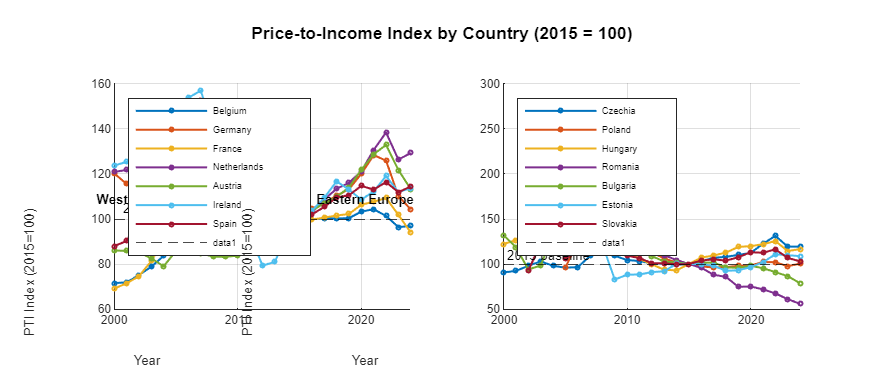

westIdx = [1, 5, 10, 19, 20, 7, 9];   % indices in countries list
eastIdx = [3, 21, 17, 23, 2, 6, 25];

figure('Name','PTI Index - West vs East','Position',[100 100 1200 500]);

subplot(1,2,1);
hold on;
cmap_w = lines(length(westIdx));
for k = 1:length(westIdx)
    i = westIdx(k);
    plot(years, ptiIndex(i,:), '-o', 'MarkerSize',3, ...
        'Color', cmap_w(k,:), 'LineWidth',1.5, 'DisplayName', countries{i});
end
yline(100, 'k--', '2015 baseline', 'LabelHorizontalAlignment','left');
xlabel('Year'); ylabel('PTI Index (2015=100)');
title('Western Europe'); legend('Location','northwest','FontSize',7);
grid on; xlim([2000 2024]);

subplot(1,2,2);
hold on;
cmap_e = lines(length(eastIdx));
for k = 1:length(eastIdx)
    i = eastIdx(k);
    plot(years, ptiIndex(i,:), '-o', 'MarkerSize',3, ...
        'Color', cmap_e(k,:), 'LineWidth',1.5, 'DisplayName', countries{i});
end
yline(100, 'k--', '2015 baseline', 'LabelHorizontalAlignment','left');
xlabel('Year'); ylabel('PTI Index (2015=100)');
title('Eastern Europe'); legend('Location','northwest','FontSize',7);
grid on; xlim([2000 2024]);

sgtitle('Price-to-Income Index by Country (2015 = 100)', 'FontSize',13,'FontWeight','bold');

## 4. Figure 2 – Annual Rate of Change Heatmap

----------------------------------------------------------------- Use only countries with data from 2001 onwards (non-NaN in col 2)

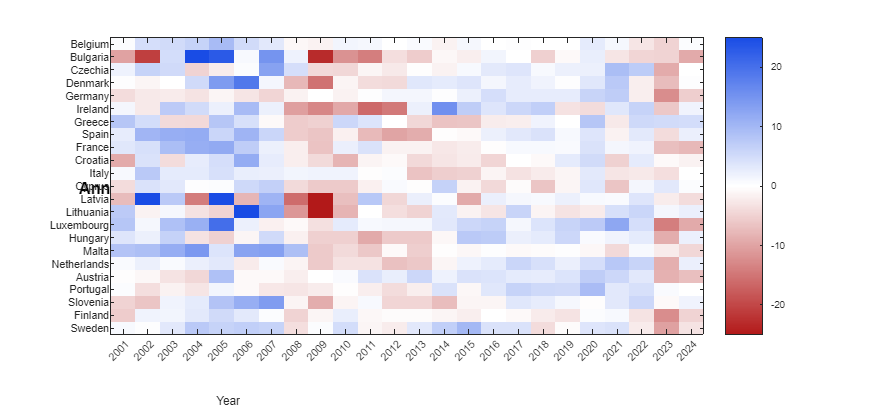

hasData = ~isnan(rateOfChange(:,2));
roc_sub = rateOfChange(hasData, 2:end);   % drop year 2000 (all NaN)
labels_sub = countries(hasData);
years_roc  = years(2:end);

figure('Name','Rate of Change Heatmap','Position',[100 100 1300 600]);
imagesc(years_roc, 1:sum(hasData), roc_sub, [-25 25]);
colormap(redblue_cm(256));
colorbar;
set(gca, 'YTick',1:sum(hasData), 'YTickLabel',labels_sub, 'FontSize',8);
xlabel('Year'); title('Annual Rate of Change in PTI Ratio (%)', 'FontSize',12,'FontWeight','bold');
xticks(years_roc); xtickangle(45);

## 5. Figure 3 – 2024 PTI Relative to Long-Term Average: Bar Chart

----------------------------------------------------------------- Sort countries by their 2024 value (most overvalued -> most undervalued)

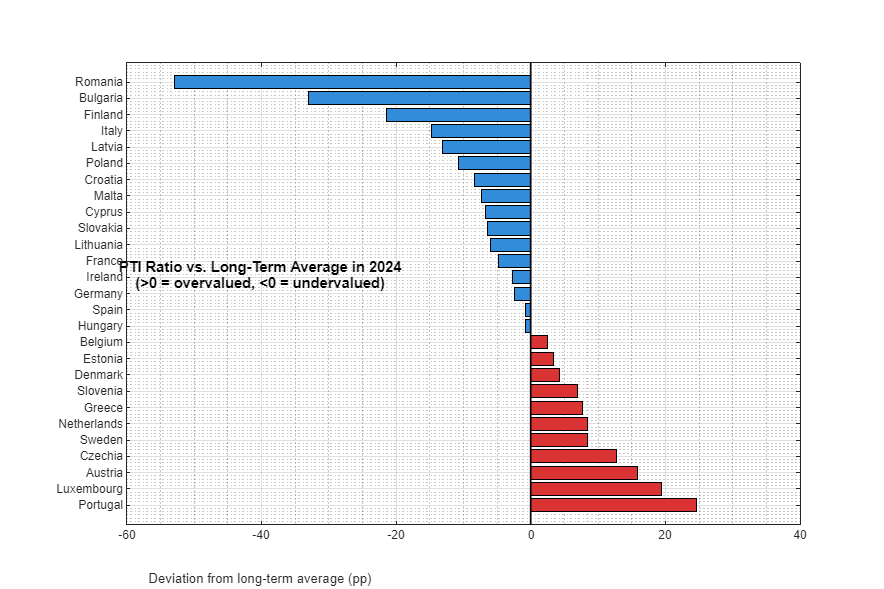

val2024 = ptiRelative(:, end);   % column 25 = year 2024
[sorted2024, sortIdx] = sort(val2024, 'descend');
sorted_names = countries(sortIdx);

figure('Name','2024 Overvaluation','Position',[100 100 900 600]);
barh(1:nCountries, sorted2024 - 100, 'FaceColor','flat');
b = findobj(gca,'Type','Bar');
colors_bar = zeros(nCountries, 3);
for k = 1:nCountries
    if sorted2024(k) > 100
        colors_bar(k,:) = [0.85 0.2 0.2];   % red = overvalued
    else
        colors_bar(k,:) = [0.2 0.55 0.85];  % blue = undervalued
    end
end
b.CData = colors_bar;
set(gca, 'YTick',1:nCountries, 'YTickLabel',sorted_names, 'FontSize',9);
xline(0, 'k-', 'LineWidth',1.5);
xlabel('Deviation from long-term average (pp)');
title({'PTI Ratio vs. Long-Term Average in 2024', ...
    '(>0 = overvalued, <0 = undervalued)'}, 'FontSize',11,'FontWeight','bold');
grid on; grid minor;

## 6. Figure 4 – Distribution of Annual Rate of Change

-----------------------------------------------------------------

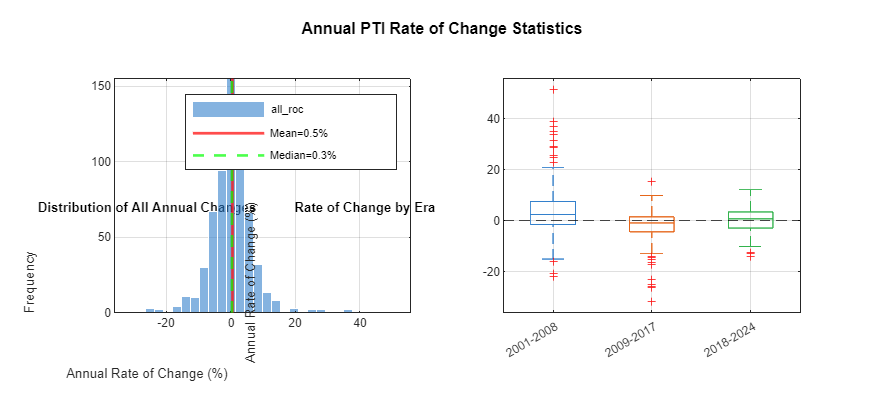

figure('Name','Distribution of Annual Changes','Position',[100 100 900 400]);

all_roc = rateOfChange(:);
all_roc = all_roc(~isnan(all_roc));

subplot(1,2,1);
histogram(all_roc, 30, 'FaceColor',[0.2 0.5 0.8], 'EdgeColor','w');
xline(mean(all_roc),'r-','LineWidth',2,'DisplayName',sprintf('Mean=%.1f%%',mean(all_roc)));
xline(median(all_roc),'g--','LineWidth',2,'DisplayName',sprintf('Median=%.1f%%',median(all_roc)));
xlabel('Annual Rate of Change (%)'); ylabel('Frequency');
title('Distribution of All Annual Changes'); legend; grid on;

subplot(1,2,2);
% Box plot by decade
dec1 = rateOfChange(:,2:9);    dec1 = dec1(~isnan(dec1(:)));   % 2001-2008
dec2 = rateOfChange(:,10:18);  dec2 = dec2(~isnan(dec2(:)));   % 2009-2017
dec3 = rateOfChange(:,19:25);  dec3 = dec3(~isnan(dec3(:)));   % 2018-2024
maxLen = max([length(dec1) length(dec2) length(dec3)]);
M = NaN(maxLen, 3);
M(1:length(dec1),1)=dec1; M(1:length(dec2),2)=dec2; M(1:length(dec3),3)=dec3;
boxplot(M, {'2001-2008','2009-2017','2018-2024'}, ...
    'Colors',[0.2 0.5 0.8; 0.9 0.4 0.1; 0.2 0.7 0.3]);
yline(0,'k--');
ylabel('Annual Rate of Change (%)');
title('Rate of Change by Era'); grid on;

sgtitle('Annual PTI Rate of Change Statistics', 'FontSize',12,'FontWeight','bold');

## 7. Figure 5 – Countries with Largest PTI Gains & Losses (2000→2024)

----------------------------------------------------------------- Change from first available year to 2024

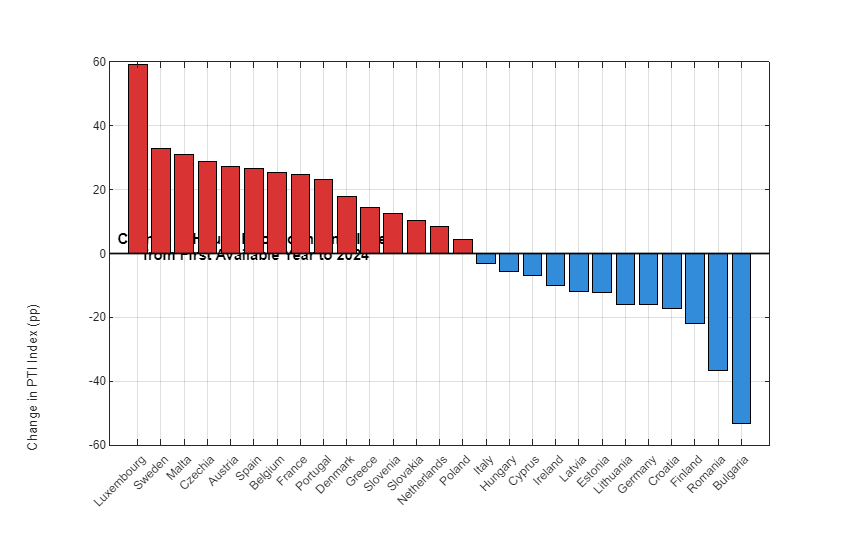

ptiChange = NaN(nCountries,1);
for i = 1:nCountries
    d = ptiIndex(i,:);
    firstValid = find(~isnan(d), 1, 'first');
    if ~isempty(firstValid) && ~isnan(d(end))
        ptiChange(i) = d(end) - d(firstValid);
    end
end

[sortedChange, chIdx] = sort(ptiChange, 'descend', 'MissingPlacement','last');
valid_mask = ~isnan(sortedChange);
sortedChange = sortedChange(valid_mask);
chNames = countries(chIdx(valid_mask));
n_valid = length(sortedChange);

figure('Name','PTI Change 2000-2024','Position',[100 100 850 550]);
bar_colors = zeros(n_valid, 3);
for k = 1:n_valid
    if sortedChange(k) >= 0
        bar_colors(k,:) = [0.85 0.2 0.2];
    else
        bar_colors(k,:) = [0.2 0.55 0.85];
    end
end
b2 = bar(1:n_valid, sortedChange, 'FaceColor','flat');
b2.CData = bar_colors;
set(gca,'XTick',1:n_valid,'XTickLabel',chNames,'XTickLabelRotation',45,'FontSize',9);
yline(0,'k-','LineWidth',1.5);
ylabel('Change in PTI Index (pp)');
title({'Change in House Price-to-Income Index', 'from First Available Year to 2024'}, ...
    'FontSize',11,'FontWeight','bold');
grid on;

## 8. Figure 6 – Cross-Country Scatter: 2024 PTI Level vs. 2024 Rate of Change

-----------------------------------------------------------------

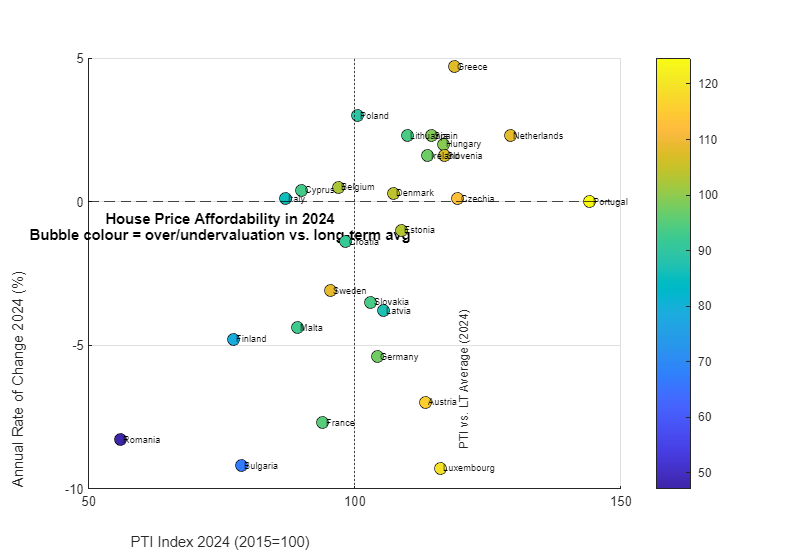

pti_2024   = ptiIndex(:, end);
roc_2024   = rateOfChange(:, end);
valid_both = ~isnan(pti_2024) & ~isnan(roc_2024);

figure('Name','Scatter 2024','Position',[100 100 800 550]);
scatter(pti_2024(valid_both), roc_2024(valid_both), 80, ...
    ptiRelative(valid_both,end), 'filled', 'MarkerEdgeColor','k');
colorbar; colormap(parula);
clb = colorbar; clb.Label.String = 'PTI vs. LT Average (2024)';
xlabel('PTI Index 2024 (2015=100)');
ylabel('Annual Rate of Change 2024 (%)');
title({'House Price Affordability in 2024', ...
    'Bubble colour = over/undervaluation vs. long-term avg'}, ...
    'FontSize',11,'FontWeight','bold');

% Label each country
c_idx = find(valid_both);
for k = 1:length(c_idx)
    text(pti_2024(c_idx(k))+0.5, roc_2024(c_idx(k)), ...
        countries{c_idx(k)}, 'FontSize',7, 'Interpreter','none');
end
yline(0,'k--'); xline(100,'k:'); grid on;

## 9. Summary Statistics Table

-----------------------------------------------------------------

fprintf('\n--- Summary: PTI Relative to Long-Term Average (2024) ---\n');


--- Summary: PTI Relative to Long-Term Average (2024) ---


fprintf('%-22s %10s %10s\n','Country','2024 Value','Status');

Country                2024 Value     Status


fprintf('%s\n', repmat('-',1,44));

--------------------------------------------


[~, rankIdx] = sort(ptiRelative(:,end),'descend');
for k = 1:nCountries
    i = rankIdx(k);
    v = ptiRelative(i,end);
    if isnan(v), continue; end
    if v > 105
        status = 'OVERVALUED';
    elseif v < 95
        status = 'UNDERVALUED';
    else
        status = 'Near average';
    end
    fprintf('%-22s %10.1f %10s\n', countries{i}, v, status);
end

Portugal                    124.6 OVERVALUED
Luxembourg                  119.4 OVERVALUED
Austria                     115.8 OVERVALUED
Czechia                     112.7 OVERVALUED
Sweden                      108.5 OVERVALUED
Netherlands                 108.4 OVERVALUED
Greece                      107.7 OVERVALUED
Slovenia                    106.9 OVERVALUED
Denmark                     104.2 Near average
Estonia                     103.3 Near average
Belgium                     102.5 Near average
Hungary                      99.2 Near average
Spain                        99.2 Near average
Germany                      97.6 Near average
Ireland                      97.4 Near average
France                       95.3 Near average
Lithuania                    94.0 UNDERVALUED
Slovakia                     93.6 UNDERVALUED
Cyprus                       93.3 UNDERVALUED
Malta                        92.6 UNDERVALUED
Croatia                      91.6 UNDERVALUED
Poland                       89.3 

## Helper Function: Red-Blue Colormap

-----------------------------------------------------------------

function cmap = redblue_cm(n)
% Creates a diverging red-white-blue colormap of length n.
half = floor(n/2);
r1 = [linspace(0.7,1,half)', linspace(0.1,1,half)', linspace(0.1,1,half)'];  % red->white
r2 = [linspace(1,0.1,n-half)', linspace(1,0.3,n-half)', linspace(1,0.9,n-half)'];  % white->blue
cmap = [r1; r2];
end